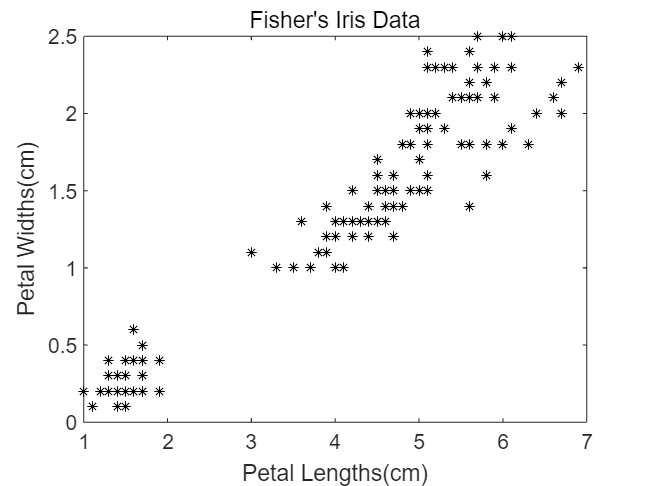

%1. Visualize the data and clustering results
load fisheriris.mat

X=meas(:,3:4);
figure;
plot(X(:,1),X(:,2),'k*','MarkerSize',5);
title 'Fisher''s Iris Data';
xlabel 'Petal Lengths(cm)';
ylabel 'Petal Widths(cm)';



%2. Cluster the data using kmeans. Specify k=3 clusters
rng(1);
[idx,C]=kmeans(X,3);

x1=min(X(:,1)):0.01:max(X(:,1));
x2=min(X(:,2)):0.01:max(X(:,2));
[x1G,x2G]=meshgrid(x1,x2);
XGrid=[x1G(:),x2G(:)];%Defines a fine grid on the plot

idx2Region=kmeans(XGrid,3,'MaxIter',1,'Start',C);

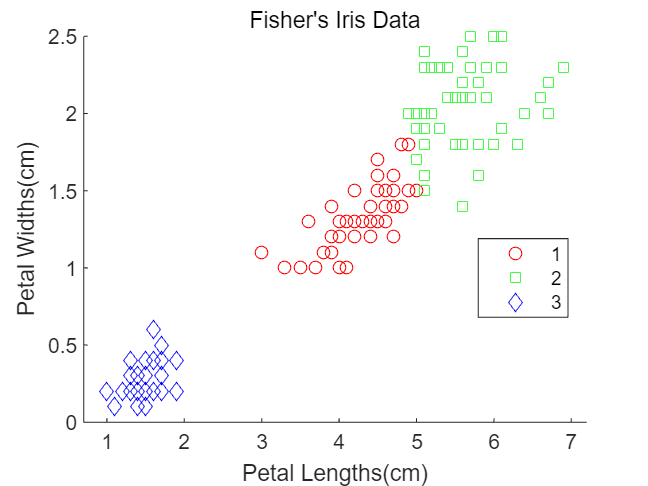


%2.1 Visualize the clustering results
figure;
hold on;
gscatter(X(:,1),X(:,2),idx,'rgb','osd');
title 'Fisher''s Iris Data';
xlabel 'Petal Lengths(cm)';
ylabel 'Petal Widths(cm)';
hold off


%2.2 Try different distance metric
rng(1);
[idx_cityblock,C_cityblock]=kmeans(X,3,"Distance","cityblock");
x1_cityblock=min(X(:,1)):0.01:max(X(:,1));
x2_cityblock=min(X(:,2)):0.01:max(X(:,2));
[x1G_cityblock,x2G_cityblock]=meshgrid(x1_cityblock,x2_cityblock);
XGrid_cityblock=[x1G_cityblock(:),x2G_cityblock(:)];%Defines a fine grid on the plot
idx2Region_cityblock=kmeans(XGrid_cityblock,3,"Distance","cityblock","MaxIter",1,'Start',C_cityblock);

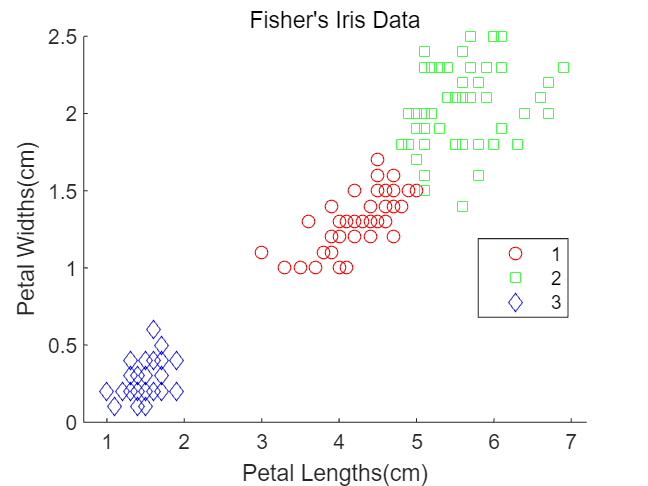

figure;
hold on;
gscatter(X(:,1),X(:,2),idx_cityblock,'rgb','osd');
title 'Fisher''s Iris Data';
xlabel 'Petal Lengths(cm)';
ylabel 'Petal Widths(cm)';
hold off

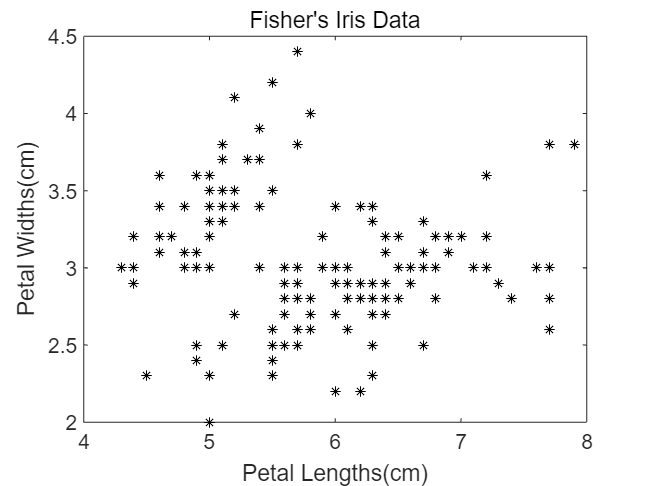


%2.3 Try different attribute features
Y=meas(:,1:2);
figure;
plot(Y(:,1),Y(:,2),'k*','MarkerSize',5);
title 'Fisher''s Iris Data';
xlabel 'Petal Lengths(cm)';
ylabel 'Petal Widths(cm)';


rng(1);
[idy,C_y]=kmeans(Y,3);

y1=min(Y(:,1)):0.01:max(Y(:,1));
y2=min(Y(:,2)):0.01:max(Y(:,2));
[y1G,y2G]=meshgrid(y1,y2);
YGrid=[y1G(:),y2G(:)];
idy2Region=kmeans(YGrid,3,'MaxIter',1,'Start',C_y);

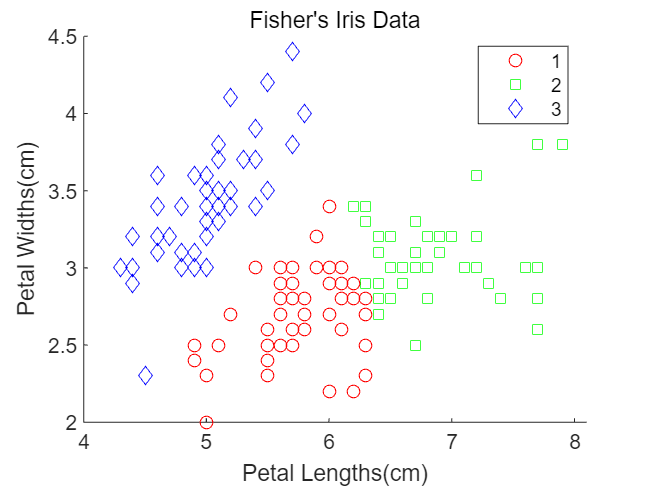

figure;
hold on;
gscatter(Y(:,1),Y(:,2),idy,'rgb','osd');
title 'Fisher''s Iris Data';
xlabel 'Petal Lengths(cm)';
ylabel 'Petal Widths(cm)';
hold off

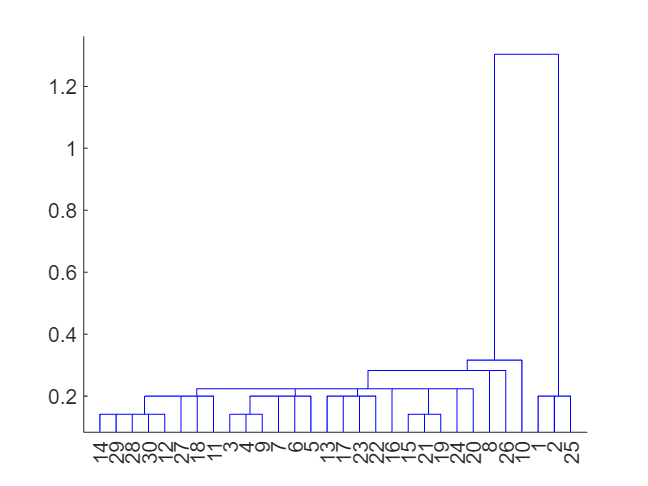


%3 Clustering using hierarchical clustering

%Load the sample data
load fisheriris.mat

%Compute four clusters of the fisheriris data using single-linkage
Z=linkage(meas(:,3:4),'single','euclidean');%create the linkage tree using single link
c=cluster(Z,'maxclust',3);

%See how the cluster assignments correspond to the three species
crosstab(c,species);

%Create a dendrogram plot of z, and visualize it.
dendrogram(Z);